# Analysis of Robust Stability (RS) and Robust Performance (RP)

load statespace_data A B C D FWT

% 2 inputs, 2 outputs
s = tf('s');
G = FWT(1:2, 1:2);

% performance weights
wp = [(s/3+0.3*2*pi)/(s+pi*6e-5) 0;
    0 0.05];

wu = [0.005 0;
       0 (0.005*s^2 + 0.0007*s+0.00005)/(s^2 + 0.0014*s + 10^(-6))];

% uncertainty weights
wi1 = ((1/(16*pi))*s + 0.3)/((1/(64*pi))*s + 1);
wi2 = wi1;

wo1 = (0.05*s + 0.25)/(0.01*s + 1);
wo2 = wo1;

wi = [wi1 0;
      0 wi2];
wo = [wo1 0;
     0 wo2];

## 3. Frequency response of weights

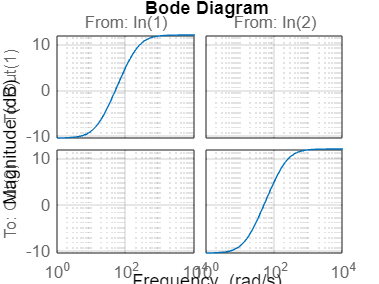

% frequency response of uncertainty weights
figure
bodemag(wi)
grid on

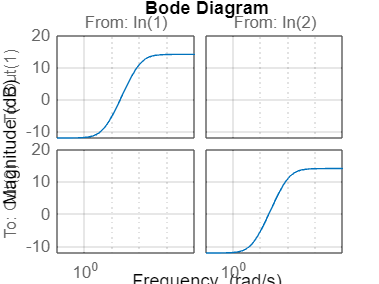


figure
bodemag(wo)
grid on

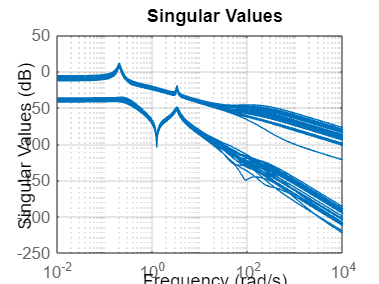


% uncertain TF singular values 

pb1 = ultidyn("idelta", 2);
pb2 = ultidyn("odelta", 2);

wid = wi*pb1;
wod = wo*pb2;

X = (eye(2)+wod)*G*(eye(2)+wid);

figure
sigma(X)
grid on

## 4. Augmented Generalised Plant

% Define plant and in- and outputs
G.u = 'udu';
G.y = 'y';

wp.u = 'v';
wp.y = 'z1';

wu.u = 'u';
wu.y = 'z2';

wo.u = 'y';
wo.y = 'do';

wi.u = 'u';
wi.y = 'di';

% Build system
sumblock1 = sumblk("ydy = y + dy", 2);
sumblock2 = sumblk("udu = u + du", 2);
sumblock3 = sumblk("v = w + ydy", 2);

dP = connect(G, wp, wu, wi, wo, sumblock1, sumblock2, sumblock3, {'du', 'dy', 'w', 'u'}, {'di', 'do', 'z1', 'z2', 'v'});

## 5. Checking NS, NP, RS, RP

load mixedsensitivitycontroller.mat MS_C P CLms Kfb_opt CLsysd CL_mimocontroller

K = MS_C;

% NS - generalised Nyquist
ol = K*G;
tdet = eye(2) - ol;

det = tdet(1,1)*tdet(2,2) - tdet(1,2)*tdet(2,1);

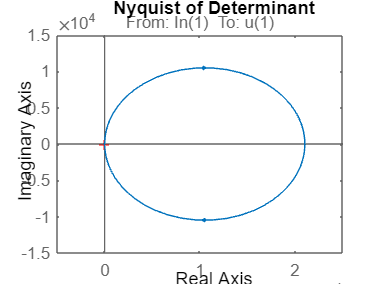


nyquist(det);
title('Nyquist of Determinant')


% NP - ||N||inf < 1
gamma = hinfnorm(CLms);

% RS
N = lft(dP, K);
M = N(1:4, 1:4);

% frequencies to check and shape of Delta block
omega=logspace(-3,4,1000);
Mf=frd(M,omega);
blockstructure =  ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 1000/1000



% norm of bound
muRS = mubnds(:,1);
[muRSinf, muRSw] = norm(muRS,inf);
muRSinf

muRSinf = 0.7471


% Evaluate at frequencies and decide structure on uncertainty
Nf = frd(N,omega);
blockstructureN =  [blockstructure;
    2 4];

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Nf, blockstructureN);

Points completed: 1000/1000



% norm of bound
muRP = mubnds(:,1);
[muRPinf, muRPw] = norm(muRP,inf);
muRPinf

muRPinf = 1.3648

# 2.2 Robust Controller Design

## 2.1 DK design

%D-K iterations

Delta=[ultidyn('D_1',[1,1]) 0 0 0; 0 ultidyn('D_2',[1,1]) 0 0; 0 0 ultidyn('D_3',[1,1]) 0; 0 0 0 ultidyn('D_4',[1,1])];

Punc=lft(Delta,dP);
opt = musynOptions('RandomStart', 3)

opt =   musyn with properties:

          Display: 'short'
          MaxIter: 10
       TargetPerf: 0
          TolPerf: 0.0100
          MixedMU: 'off'
           FullDG: [1 1]
         FitOrder: [5 2]
    FrequencyGrid: [0×1 double]
        AutoScale: 'on'
       Regularize: 'on'
        LimitGain: 'on'
      RandomStart: 3
      UseParallel: 0
         MinDecay: 1.0000e-07
     MaxFrequency: Inf



[DK, clp, dkinfo]=musyn(Punc,2,2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           12.74        9.289        9.382            22
    2           6.555        6.487        6.539            20
    3           2.339        2.029        2.052            32
    4           1.234          1.2        1.235            30
    5           1.069        1.063        1.119            32
    6           1.011        1.004        1.081            36
    7          0.9961        0.992        1.093            36
    8          0.9811       0.9766        1.042            26
    9          0.9954       0.9911        1.008            34
   10          0.9976       0.9923        1.005            36

Best achieved robust performance: 0.977



## 2.2 Checking Performances of DK

% NS and NP
NS = max(real(eig(N)))

NS = -1.8850e-04


% RS and RP
N = lft(dP, DK);

N22 = N(5:end, 5:end);
gamma_dk = hinfnorm(N22)

gamma_dk = 0.6124


M = N(1:4, 1:4);

% frequencies to check and shape of Delta block
omega=logspace(-3,4,100);
Mf=frd(M,omega);
blockstructure =  -ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 100/100



% RS
muRS = mubnds(:,1);
[muRSinf, muRSw] = norm(muRS,inf);
muRSinf

muRSinf = 0.4242


% RP
% Evaluate at frequencies and decide structure on uncertainty
Nf = frd(N,omega);
blockstructureN =  [blockstructure;
    2 4];

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Nf, blockstructureN);

Points completed: 100/100



% norm of bound
muRP = mubnds(:,1);
[muRPinf, muRPw] = norm(muRP,inf);
muRPinf

muRPinf = 0.9760

## 3. Time-domain Simulations

% H infinity Controller
%CLstep_hinf = minreal(feedback(-MS_C*X, eye(2)));
CLstep_hinf = minreal(lft(Gsim, MS_C))

Unrecognized function or variable 'Gsim'.

%CLstep_hinf = (X*MS_C)/(eye(2)+X*MS_C)

%[y, tout] = step(CLstep_hinf);

% Fixed-structure Controller
CL_fs = feedback(-Kfb_opt*X, eye(2));

%[y_fs, tout_fs] = step(CL_fs);


% DK controller
CL_dk = feedback(DK*X, eye(2));

%[y_dk, tout_dk] = step(CL_dk,450);


% Step Response Hinf, FS, DK
figure
subplot(2,1,1)
hold on
% plot(tout, y(:,1,1))
% plot(tout_fs, y_fs(:,1,1))
% plot(tout_dk, y_dk(:,1,1))
step(CL_dk)
legend('H\infty Controller','Fixed-Structure', 'DK-controller')
xlim([0, 450])
ylabel('\omega_r [rad/s]')
title('Rotor speed \omega_r')
grid on

subplot(2,1,2)
hold on
plot(tout, y(:,2,1))
plot(tout_fs, y_fs(:,2,1))
plot(tout_dk, y_dk(:,2,1))
legend('H\infty Controller','Fixed-Structure', 'DK-controller')
xlim([0, 450])
xlabel('Time [s]')
ylabel('Displacement [m]')
title('Nacelle z-displacement')
grid on

sgtitle('Step Response of H\infty, Fixed-Structure and DK-controller')

% disturbance response
warning off
systemnames ='FWT';   
inputvar ='[V; Beta; Tau]';   
input_to_FWT= '[Beta; Tau; V]';

outputvar= '[FWT; Beta; Tau; FWT]'; 
sysoutname='G_mimo';
sysic;
warning on

CLhinf_d = minreal(lft(Gsim, MS_C));
CLfs_d = minreal(lft(G_mimo, Kfb_opt));
CLdk_d = minreal(lft(G_mimo, DK));

[yd, toutd] = step(CLhinf_d);

[y_fsd, tout_fsd] = step(CLfs_d);

[y_dkd, tout_dkd] = step(CLdk_d,450);


% Disturbance Response Hinf, FS, DK
figure
% subplot(2,1,1)
step(CLhinf_d, CLfs_d, CLdk_d)
legend('H\infty Controller','Fixed-Structure', 'DK-controller')
xlim([0, 450])
ylabel('\omega_r [rad/s]')
% title('Rotor speed \omega_r')
grid on
title('')
sgtitle('Disturbance Response of H\infty, Fixed-Structure and DK-controller')

% subplot(2,1,2)
% hold on
% plot(toutd, yd(:,2,1))
% plot(tout_fsd, y_fsd(:,2,1))
% plot(tout_dkd, y_dkd(:,2,1))
% legend('H\infty Controller','Fixed-Structure', 'DK-controller')
% xlim([0, 450])
% xlabel('Time [s]')
% ylabel('Displacement [m]')
% title('Nacelle z-displacement')
% grid on

### Frequency-domain

%bodemag
figure
bodemag(MS_C, Kfb_opt, DK)
legend('H\infty Controller', 'Fixed-Structure', 'DK-controller')
grid on

%sensitivity
hinf_sens = loopsens(G, MS_C);
fs_sens = loopsens(G, Kfb_opt);
dk_sens = loopsens(G, DK);

figure
bodemag(hinf_sens.Si, fs_sens.Si, dk_sens.Si)
title('Bode Diagram of Sensitivity Function')
legend('H\infty Controller', 'Fixed-Structure', 'DK-controller')
grid on

figure
bodemag(hinf_sens.Ti, fs_sens.Ti, dk_sens.Ti)
title('Bode Diagram of Complementary Sensitivity Function')
legend('H\infty Controller', 'Fixed-Structure', 'DK-controller')
grid on